# Estimación de parámetros para modelos tipo SIR

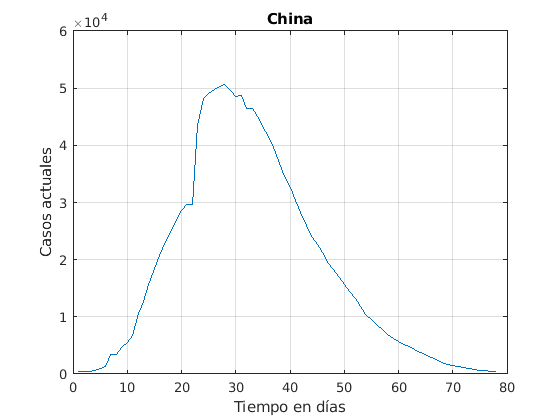


addpath(genpath("Tool"))
load("RealDataExamples/China.mat")
close all


plot(ActualCases)
grid on
xlabel("Tiempo en días")
ylabel("Casos actuales")
title("China")

syms S(t) I(t) R(t)
syms beta gamma

ode1 = diff(S) == -beta*S*I/(S+R+I);
ode2 = diff(I) == beta*S*I/(S+R+I) - gamma*I;
ode3 = diff(R) == gamma*I;
odes = [ode1; ode2; ode3]

$$odes(t) = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}S\left(t\right)=-\sigma_{1}\\ \frac{\partial }{\partial t}\text{I}\left(t\right)=\sigma_{1}-\gamma \,\text{I}\left(t\right)\\ \frac{\partial }{\partial t}R\left(t\right)=\gamma \,\text{I}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\beta \,\text{I}\left(t\right)\,S\left(t\right)}{\text{I}\left(t\right)+R\left(t\right)+S\left(t\right)} \end{array}$$


vars = [S I R];

domain = [0 length(ActualCases)-1];
xdata = 0:1:length(ActualCases)-1;

modelName = 'Lotka-Volterra';
gsua_dataprep(odes, vars, domain, modelName);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccc} S\left(t\right) & \text{I}\left(t\right) & R\left(t\right) & \beta & \gamma \end{array}\right)$$

Ranges = [0 5e8;      %S
          0 2000;     %I
          20 1000;    %R
          0 1;       %beta
          0 1;       %gamma
          ];

[T, ~] = gsua_dataprep(odes, vars, domain, modelName, 'Range', Ranges);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccc} S\left(t\right) & \text{I}\left(t\right) & R\left(t\right) & \beta & \gamma \end{array}\right)$$

Generating a valid matrix for estimations
Estimation 1
Estimation 2
Estimation 3
Estimation 4
Estimation 5
Estimation 6
Estimation 7
Estimation 8
Estimation 9


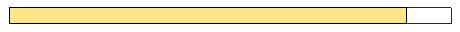

Estimation 10


T.Properties.CustomProperties.output = 2;

N = 100;

opt = optimoptions('lsqcurvefit', 'UseParallel',false,'Display','off');
solver = 'lsqc';

[T_est, ~] = gsua_pe(T, xdata, ActualCases', 'solver', solver, 'N', N, 'opt', opt); 

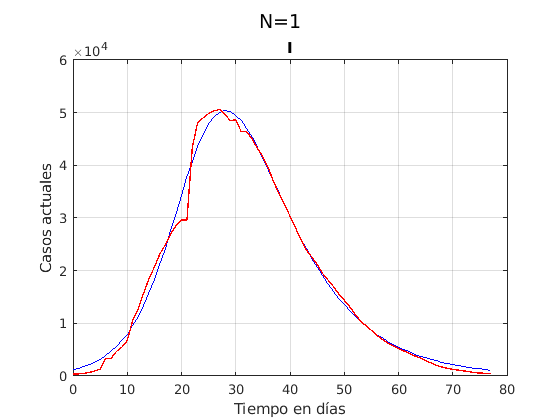

figure
gsua_eval(T_est.Estlsqc(:,1), T_est, xdata, ActualCases);
grid on
ylabel("Casos actuales")
xlabel("Tiempo en días")

figure
gsua_eval(T_est.Estlsqc(:,1:10), T_est, xdata, ActualCases);

Sim10 Done
Sim9 Done
Sim8 Done
Sim7 Done
Sim6 Done
Sim5 Done
Sim4 Done
Sim3 Done
Sim2 Done
Sim1 Done


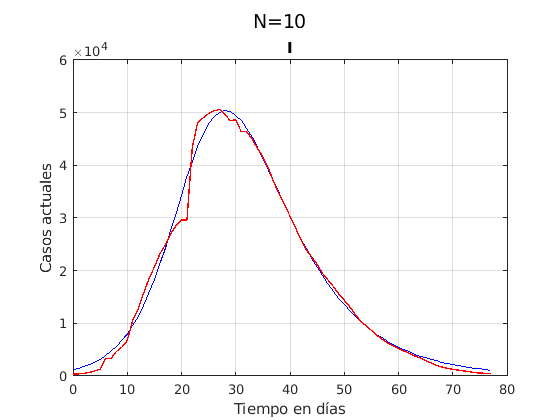

grid on
ylabel("Casos actuales")
xlabel("Tiempo en días")

T_est

T_est = 5×3 table
                Range       Nominal      Estlsqc   
             ___________    _______    ____________

    S0        0    5e+08    2.5e+08    1×100 double
    I0        0     2000       1000    1×100 double
    R0       20     1000        510    1×100 double
    beta      0        1        0.5    1×100 double
    gamma     0        1        0.5    1×100 double


T.Properties.CustomProperties.output = 2:3;

N = 100;

opt = optimoptions('lsqcurvefit', 'UseParallel',false,'Display','off');
solver = 'lsqc';

[T_est, ~] = gsua_pe(T, xdata, [ActualCases; Recovered]', 'solver', solver, 'N', N, 'opt', opt); 

Generating a valid matrix for estimations
Estimation 1
Estimation 2
Estimation 3
Estimation 4
Estimation 5
Estimation 6
Estimation 7
Estimation 8
Estimation 9
Estimation 10
Estimation 11
Estimation 12
Estimation 13
Estimation 14
Estimation 15
Estimation 16
Estimation 17
Estimation 18
Estimation 19
Estimation 20
Estimation 21


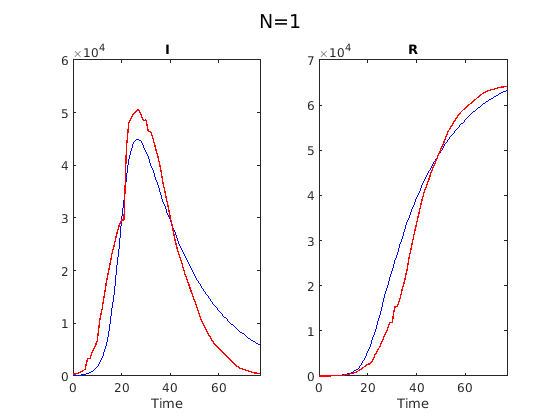

figure
gsua_eval(T_est.Estlsqc(:,1), T_est, xdata, [ActualCases; Recovered]);

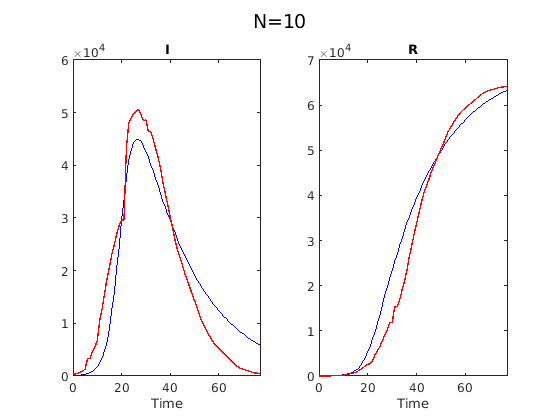

Sim10 Done
Sim9 Done
Sim8 Done
Sim7 Done
Sim6 Done
Sim5 Done
Sim4 Done
Sim3 Done
Sim2 Done
Sim1 Done


figure
gsua_eval(T_est.Estlsqc(:,1:10), T_est, xdata, [ActualCases; Recovered]);

T_est

T_est = 5×3 table
                Range       Nominal      Estlsqc   
             ___________    _______    ____________

    S0        0    5e+08    2.5e+08    1×100 double
    I0        0     2000       1000    1×100 double
    R0       20     1000        510    1×100 double
    beta      0        1        0.5    1×100 double
    gamma     0        1        0.5    1×100 double
